clear
rng(203829)
addpath('functions')
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
plotPos = [100 100 800, 400];
plotPos2 = [100 100 800, 600];


## Question 1.1

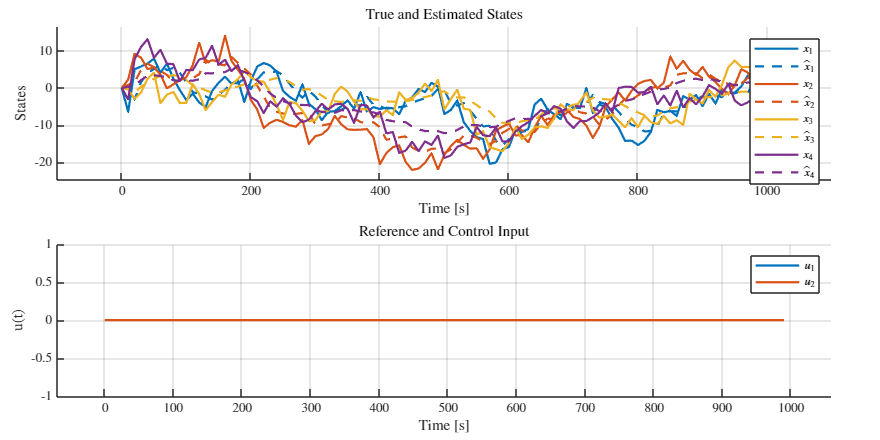

%% --- system definition ---
Ts = 10;    % sample time [s]

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];

B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];

C = [1, 0, 0, 0;
     0, 1, 0, 0];

% cost / noise‐covariance matrices (as given)
R1= [8.0209, 0.2260, 1.5334, 0.0812;
       0.2260, 8.0209, 0.0812, 1.5334;
       1.5334, 0.0812, 7.4082, 0.0172;
       0.0812, 1.5334, 0.0172, 7.4082];

R2 = eye(2);    % = R2

%% --- LQR controller design ---
ctrlOn = 0;
[K,~,~] = dlqr(A,B,diag([1,1,0,0]),R2*250);
dcG = (C*(eye(4) - (A-B*K))^(-1) * B)^-1;

%% --- Kalman filter design (steady‐state) ---
%   L is the state‐estimator gain:  xhat+ = A*xhat + B*u + L*(y - C*xhat)
% Solve the discrete Riccati equation
[P,~,~] = dare(A', C', R1, R2);
[Pp,~,~] = idare(A', C', R1, R2);

Po = inv(inv(Pp) + C'*inv(R2)*C);

% Compute stationary Kalman gain
% Kf = P * C' / (C * P * C' + R2);
Kf = Po * C' / (C * Po * C' + R2);


%% --- simulation setup ---
Tfinal = 1000;            % total simulation time [s]
N = Tfinal / Ts;         % number of steps
x     = zeros(4, N+1);   % true state
xhat  = zeros(4, N+1);   % estimated state
y     = zeros(2, N);     % measurements
yhat  = zeros(2, N);     % predicted outputs
u     = zeros(2, N);     % control inputs

rng(0);  % for reproducible noise

T = N; % Periode in sampels
ref1 = 50*square(2*pi*1/T*(1:N),50);
ref2 = zeros(1,N);
ref = [ref1;ref2];


for k = 1:N
    % Simulate measurement
    v = mvnrnd(zeros(size(R2,1),1), R2)';
    y(:,k) = C*x(:,k) + v;

    % Controller (if any)
    if ctrlOn
        u(:,k) = -K*xhat(:,k) + dcG * ref(:,k);
    end
    % True system evolution
    w = mvnrnd(zeros(size(R1,1),1), R1)';
    x(:,k+1) = A*x(:,k) + B*u(:,k) + w;

    % Stationary Kalman filter update
    innov = y(:,k) - C*xhat(:,k);
    xhat(:,k + 1) = A*xhat(:,k) + B*u(:,k) + Kf*innov;
    yhat(:,k + 1) = C*xhat(:,k);
end

time = 0:Ts:Tfinal;
colors = lines(4);
%% --- plotting ---
fig = figure();
fig.Position = plotPos;
tiledlayout(2,1, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
names = {'$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'};
if ctrlOn
    stairs(time(1:end-1), ref(1,:), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
    names = {'$r_1$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'};
end
hold on
for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend(names, ...
       'Location','northeast');
title('True and Estimated States');
ylim padded;
xlim padded;
grid on;
hold off

% Plot control input
nexttile;
hold on
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');
ylim padded;
xlim padded;
grid on;
hold off
filePath = fullfile("output", 'question_1_1.png');
exportgraphics(fig, filePath, 'Resolution', 600);

## Question 1.2

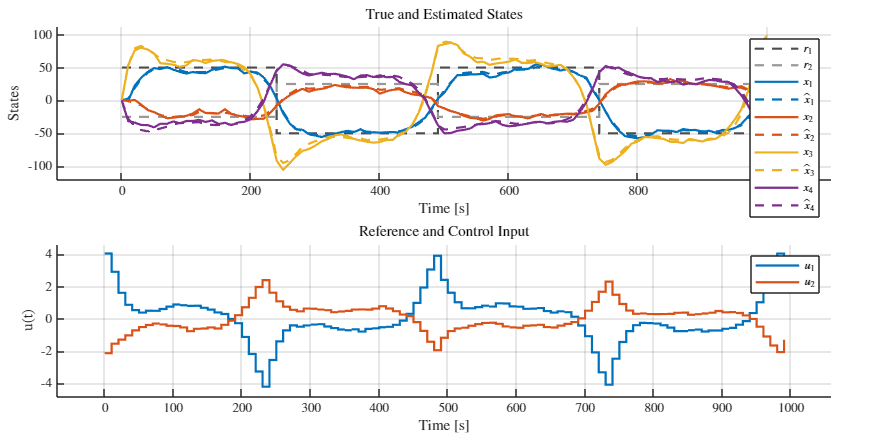

%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0];

D = zeros(2,2);

[nx, nu] = size(B);
ny        = size(C,1);

R1 = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
R2 = eye(ny);                           % meas‐noise cov
[ Lf, P, ~ ] = dlqe(A, eye(nx), C, R1, R2);  

% [P,~,~] = dare(A', C', Q, R);
[Pp,~,~] = idare(A', C', R1, R2);

Po = inv(inv(Pp) + C'*inv(R2)*C);

% Compute stationary Kalman gain
% Kf = P * C' / (C * P * C' + R2);
Kf = Po * C' / (C * Po * C' + R2);

%% 3) GPC tuning parameters
Np  = 10; % prediction horizon
% Np = Nsim
Qy  = kron(eye(Np), 1*eye(ny));                  % output‐tracking weight
Ru  = 100 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Phi     = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);

for i = 1:Np
    Phi((i-1)*ny+1:i*ny, :) = C * A^(i-1);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;

        if i == j
            Gamma_y(idx_row, idx_col) = D;  % Diagonal: D
        else
            Gamma_y(idx_row, idx_col) = C * A^(i-j) * B;  % Lower-triangular: CA^(i-j)B
        end
    end
end
%% 5) Reference signal 
ref1 = 50 * square(2*pi*(2/(Nsim))*(1:Nsim + Np), 50);
ref2 = -0.5*ref1; %zeros(1, Nsim + Np);
ref  = [ref1; ref2];    

%% 6) Preallocate
x     = zeros(nx,   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
xhat_pred = xhat(:,1);

rng(0);  % for reproducibility

%% 7) Main simulation loop

for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), R2)';
       
    %--- Kalman correct
    innov      = y(:,k) - C*xhat_pred;
    xhat(:,k)  = xhat_pred + Kf * innov;
    
    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference

    %--- apply control law
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;
    
    %--- simulate true system with process noise
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx, 1), R1)';
    
    %--- Kalman predict
    xhat_pred = A*xhat(:,k) + B*u(:, k);

end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

fig = figure();
fig.Position = plotPos;
tiledlayout(2,1, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
hold on
stairs(time(1:end-1), ref(1,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
stairs(time(1:end-1), ref(2,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.6 0.6 0.6]);
names = {'$r_1$', '$r_2$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'};


for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend(names, ...
       'Location','northeast');
title('True and Estimated States');
ylim padded;
xlim padded;
grid on;
hold off

% Plot control input
nexttile;
hold on
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');
ylim padded;
xlim padded;
grid on;
hold off
filePath = fullfile("output", 'question_1_2.png');
exportgraphics(fig, filePath, 'Resolution', 300);

## Question 1.3


%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0;];



[nx, nu] = size(B);
ny        = size(C,1);

%% 2) Kalman filter design (steady‐state gain)
R1 = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
R2 = eye(ny);                           % meas‐noise cov


kappa = [0.999,0.999];
% kappa = [0.99999,0.99999,0.99999,0.99999];
sigma_d = 2*[1,1];
A_aug = [A,[zeros(2,2);eye(2,2)];zeros(2,4),diag(kappa)];
% A_aug = [A,eye(4,2);zeros(2,4),diag(kappa)]
B_aug = [B;zeros(2,2)];
C_aug =  [C, zeros(2,2)];
D_aug = D;
R1_aug = [R1,zeros(4,2);zeros(2,4),diag(sigma_d.^2)];
rank(obsv(A_aug,C_aug))

ans = 6

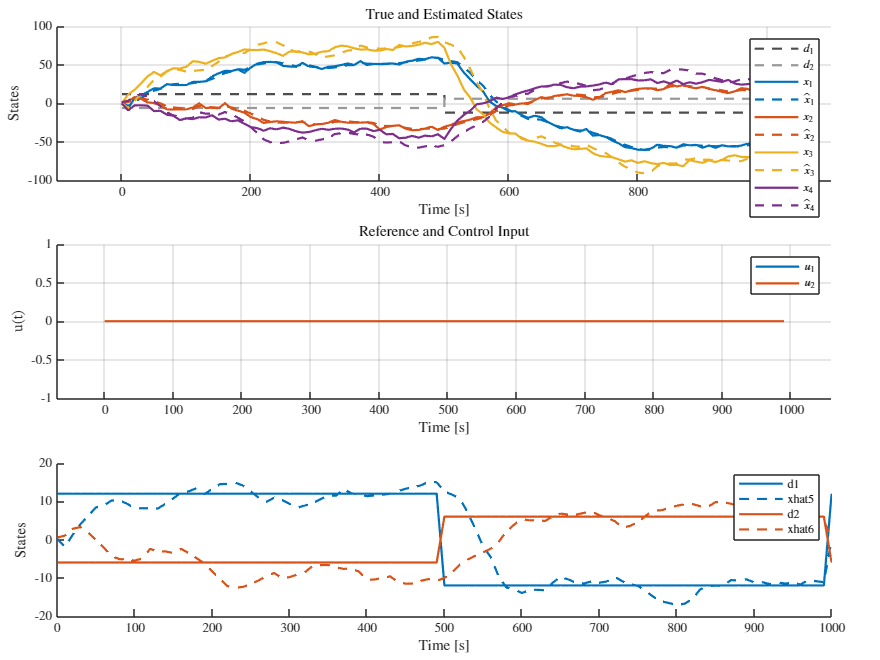



[nx, nu] = size(B_aug);
ny        = size(C_aug,1);


[ Kf, ~, ~ ] = dlqe(A_aug, eye(nx), C_aug, R1_aug, R2);  
[Pp,~,~] = idare(A_aug', C_aug', R1_aug, R2);

Po = inv(inv(Pp) + C_aug'*inv(R2)*C_aug);

% Compute stationary Kalman gain
% Kf = P * C' / (C * P * C' + R2);
Kf = Po * C_aug' / (C_aug * Po * C_aug' + R2);


%% 3) GPC tuning parameters
Np  = 10;                                      % prediction horizon
Qy  = kron(eye(Np), eye(ny));                  % output‐tracking weight
Ru  = 100 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Phi     = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);

for i = 1:Np
    Phi((i-1)*ny+1:i*ny, :) = C_aug * A_aug^(i-1);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;

        if i == j
            Gamma_y(idx_row, idx_col) = D_aug;  % Diagonal: D
        else
            Gamma_y(idx_row, idx_col) = C_aug * A_aug^(i-j) * B_aug;  % Lower-triangular: CA^(i-j)B
        end
    end
end

% Precompute Hessian for QP
H = Gamma_y' * Qy * Gamma_y + Ru;
opts = optimoptions('quadprog','Display','off');

%% 5) Reference signal (±10 square wave on output 1)
ref1 = 50 * square(2*pi*(2/(Nsim+ Np))*(1:Nsim + Np), 50);
ref2 = -0.5*ref1; %zeros(1, Nsim + Np);
ref  = [ref1; ref2];    


%% 6) Preallocate
x     = zeros(nx-2,   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
d  = [12* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    -6* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    ];   % estimated state
% d = 100*[ones(1,Nsim+1);
%     -ones(1,Nsim+1)];

u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
xhat_pred = xhat(:,1);
Xpred   = zeros(nx, Np+1, Nsim);  % store Np‐step predictions
rng(0);  % for reproducibility

%% 7) Main simulation loop
for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), R2)';
    
    %--- Kalman correct
    innov      = y(:,k) - C_aug*xhat_pred;
    xhat(:,k)  = xhat_pred + Kf * innov;

    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference
    f = Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);

    %--- apply control law
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;
    u(:, k) =  [0;0];

    
    % Compute Np‐step ahead state predictions
    Xpred(:,1,k) = xhat(:,k);
    for j = 1:Np
    Uj = U_N((j-1)*nu+1:j*nu);
    Xpred(:,j+1,k) = A_aug*Xpred(:,j,k) + B_aug*Uj;
    end
    
    
    %--- simulate true system with process noise
    % x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx-2, 1), Qk_f)' + [eye(2,2);zeros(2,2)] *d(:,k);
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx-2, 1), R1)' + [zeros(2,2);eye(2,2)] *d(:,k);
        
    %--- Kalman predict
    xhat_pred = A_aug*xhat(:,k) + B_aug*u(:, k);
end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

fig = figure();
fig.Position = plotPos2;
tiledlayout(3,1, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
hold on
stairs(time(1:end), d(1,1:end), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
stairs(time(1:end), d(2,1:end), '--', 'LineWidth', 1.5, 'Color', [0.6 0.6 0.6]);
names = {'$d_1$', '$d_2$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'};


for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend(names, ...
       'Location','northeast');
title('True and Estimated States');
ylim padded;
xlim padded;
grid on;
hold off

% Plot control input
nexttile;
hold on
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');
ylim padded;
xlim padded;
grid on;
hold off
% filePath = fullfile("output", 'question_1_4.png');
% exportgraphics(fig, filePath, 'Resolution', 300);

% fig = figure();
% fig.Position = plotPos;
% tiledlayout(1,1, 'Padding', 'compact', 'TileSpacing', 'compact');
nexttile;
hold on
for i = 5:6
    plot(time,  d(i-4,:),     '-',  'Color', colors(i-4,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i-4,:), 'LineWidth', 1.5);
end
hold off
xlabel('Time [s]');
ylabel('States');
legend([strcat("d",string(1:2));strcat("xhat",string(5:6))], ...
       'Interpreter','latex','Location','northeast');
filePath = fullfile("output", 'question_1_3.png');
exportgraphics(fig, filePath, 'Resolution', 300);

## Question 1.4

%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0;];
D= zeros(2,2);

[nx, nu] = size(B);
ny        = size(C,1);

%% 2) Kalman filter design (steady‐state gain)
R1 = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
R2 = eye(ny);                           % meas‐noise cov


kappa = [0.999,0.999];
% kappa = [0.99999,0.99999,0.99999,0.99999];
sigma_d = 2*[1,1];
A_aug = [A,[zeros(2,2);eye(2,2)];zeros(2,4),diag(kappa)];
% A_aug = [A,eye(4,2);zeros(2,4),diag(kappa)]
B_aug = [B;zeros(2,2)];
C_aug =  [C, zeros(2,2)];
D_aug = D;
R1_aug = [R1,zeros(4,2);zeros(2,4),diag(sigma_d.^2)];
rank(obsv(A_aug,C_aug))

ans = 6

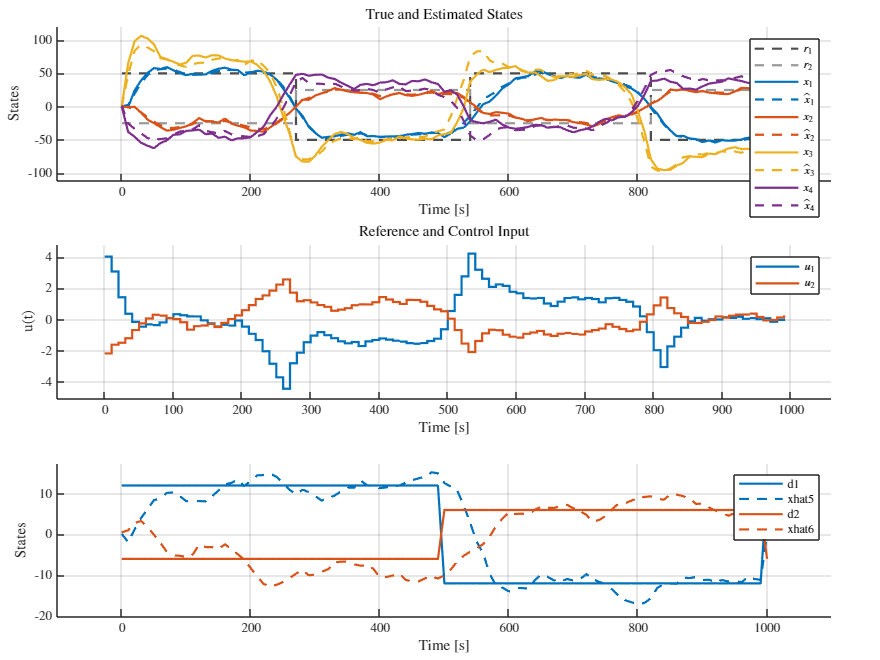



[nx, nu] = size(B_aug);
ny        = size(C_aug,1);


[ Kf, ~, ~ ] = dlqe(A_aug, eye(nx), C_aug, R1_aug, R2);  
[Pp,~,~] = idare(A_aug', C_aug', R1_aug, R2);

Po = inv(inv(Pp) + C_aug'*inv(R2)*C_aug);

% Compute stationary Kalman gain
% Kf = P * C' / (C * P * C' + R2);
Kf = Po * C_aug' / (C_aug * Po * C_aug' + R2);


%% 3) GPC tuning parameters
Np  = 10;                                      % prediction horizon
Qy  = kron(eye(Np), eye(ny));                  % output‐tracking weight
Ru  = 100 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Phi     = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);

for i = 1:Np
    Phi((i-1)*ny+1:i*ny, :) = C_aug * A_aug^(i-1);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;

        if i == j
            Gamma_y(idx_row, idx_col) = D_aug;  % Diagonal: D
        else
            Gamma_y(idx_row, idx_col) = C_aug * A_aug^(i-j) * B_aug;  % Lower-triangular: CA^(i-j)B
        end
    end
end

% Precompute Hessian for QP
H = Gamma_y' * Qy * Gamma_y + Ru;
opts = optimoptions('quadprog','Display','off');

%% 5) Reference signal (±10 square wave on output 1)
ref1 = 50 * square(2*pi*(2/(Nsim+ Np))*(1:Nsim + Np), 50);
ref2 = -0.5*ref1; %zeros(1, Nsim + Np);
ref  = [ref1; ref2];    


%% 6) Preallocate
x     = zeros(nx-2,   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
d1  = [12* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    -6* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    ];   % estimated state

d2 =[12* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    -6* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    -4* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    8* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50)]; 
% d = 100*[ones(1,Nsim+1);
%     -ones(1,Nsim+1)];

u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
xhat_pred = xhat(:,1);
Xpred   = zeros(nx, Np+1, Nsim);  % store Np‐step predictions
rng(0);  % for reproducibility

%% 7) Main simulation loop
for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), R2)';
    
    %--- Kalman correct
    innov      = y(:,k) - C_aug*xhat_pred;
    xhat(:,k)  = xhat_pred + Kf * innov;

    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference
    f = Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);

    %--- apply control law
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;
    % u(:, k) =  [0;0];

    
    % Compute Np‐step ahead state predictions
    Xpred(:,1,k) = xhat(:,k);
    for j = 1:Np
    Uj = U_N((j-1)*nu+1:j*nu);
    Xpred(:,j+1,k) = A_aug*Xpred(:,j,k) + B_aug*Uj;
    end
    
    
    %--- simulate true system with process noise
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx-2, 1), R1)' + [zeros(2,2);eye(2,2)] *d1(:,k);
    % x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx-2, 1), R1)' + eye(4)*d2(:,k);
        
    %--- Kalman predict
    xhat_pred = A_aug*xhat(:,k) + B_aug*u(:, k);
end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

fig = figure();
fig.Position = plotPos2;
tiledlayout(3,1, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
hold on
stairs(time(1:end-1), ref(1,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
stairs(time(1:end-1), ref(2,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.6 0.6 0.6]);
names = {'$r_1$', '$r_2$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'};


for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend(names, ...
       'Location','northeast');
title('True and Estimated States');
ylim padded;
xlim padded;
grid on;
hold off

% Plot control input
nexttile;
hold on
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');
ylim padded;
xlim padded;
grid on;
hold off
% filePath = fullfile("output", 'question_1_4.png');
% exportgraphics(fig, filePath, 'Resolution', 300);
% fig = figure();
% fig.Position = plotPos;
% tiledlayout(1,1, 'Padding', 'compact', 'TileSpacing', 'compact');
nexttile;
hold on
for i = 5:6
    plot(time,  d1(i-4,:),     '-',  'Color', colors(i-4,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i-4,:), 'LineWidth', 1.5);
end
hold off
xlabel('Time [s]');
ylabel('States');
ylim padded;
xlim padded;
grid on
legend([strcat("d",string(1:2));strcat("xhat",string(5:6))], ...
       'Interpreter','latex','Location','northeast');
filePath = fullfile("output", 'question_1_4.png');
exportgraphics(fig, filePath, 'Resolution', 300);

## Bonus 1.4.1

%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0;];



[nx, nu] = size(B);
ny        = size(C,1);

%% 2) Kalman filter design (steady‐state gain)
R1 = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
R2 = eye(ny);                           % meas‐noise cov


kappa = [0.999,0.999];
% kappa = [0.99999,0.99999,0.99999,0.99999];
sigma_d = 2*[1,1];
A_aug = [A,[zeros(2,2);eye(2,2)];zeros(2,4),diag(kappa)];
% A_aug = [A,eye(4,2);zeros(2,4),diag(kappa)]
B_aug = [B;zeros(2,2)];
C_aug =  [C, zeros(2,2)];
D_aug = D;
R1_aug = [R1,zeros(4,2);zeros(2,4),diag(sigma_d.^2)];
rank(obsv(A_aug,C_aug))

ans = 6

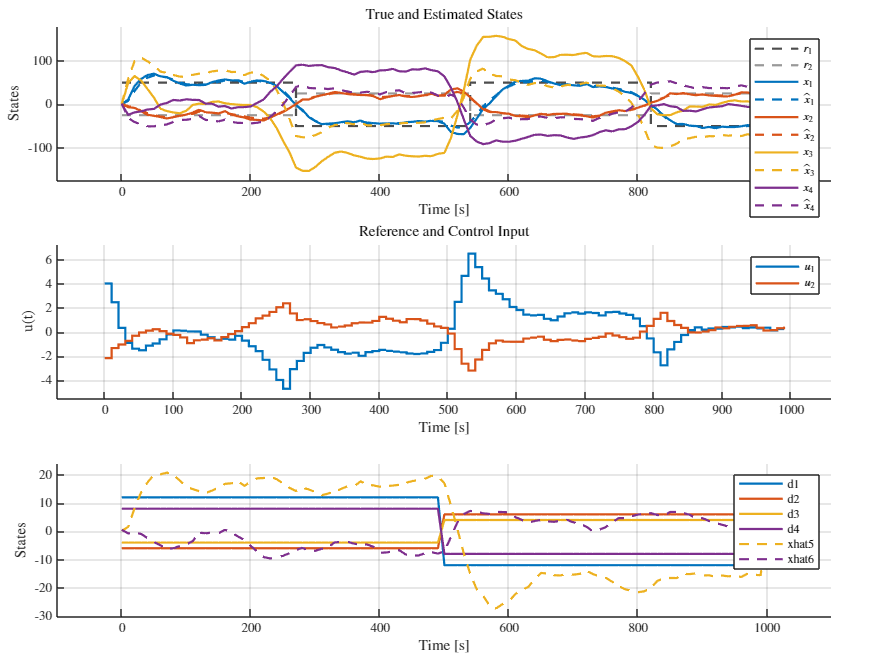



[nx, nu] = size(B_aug);
ny        = size(C_aug,1);


[ Kf, ~, ~ ] = dlqe(A_aug, eye(nx), C_aug, R1_aug, R2);  
[Pp,~,~] = idare(A_aug', C_aug', R1_aug, R2);

Po = inv(inv(Pp) + C_aug'*inv(R2)*C_aug);

% Compute stationary Kalman gain
% Kf = P * C' / (C * P * C' + R2);
Kf = Po * C_aug' / (C_aug * Po * C_aug' + R2);


%% 3) GPC tuning parameters
Np  = 10;                                      % prediction horizon
Qy  = kron(eye(Np), eye(ny));                  % output‐tracking weight
Ru  = 100 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Phi     = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);

for i = 1:Np
    Phi((i-1)*ny+1:i*ny, :) = C_aug * A_aug^(i-1);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;

        if i == j
            Gamma_y(idx_row, idx_col) = D_aug;  % Diagonal: D
        else
            Gamma_y(idx_row, idx_col) = C_aug * A_aug^(i-j) * B_aug;  % Lower-triangular: CA^(i-j)B
        end
    end
end

% Precompute Hessian for QP
H = Gamma_y' * Qy * Gamma_y + Ru;
opts = optimoptions('quadprog','Display','off');

%% 5) Reference signal (±10 square wave on output 1)
ref1 = 50 * square(2*pi*(2/(Nsim+ Np))*(1:Nsim + Np), 50);
ref2 = -0.5*ref1; %zeros(1, Nsim + Np);
ref  = [ref1; ref2];    


%% 6) Preallocate
x     = zeros(nx-2,   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
d1  = [12* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    -6* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    ];   % estimated state

d2 =[12* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    -6* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    -4* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    8* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50)]; 
% d = 100*[ones(1,Nsim+1);
%     -ones(1,Nsim+1)];

u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
xhat_pred = xhat(:,1);
Xpred   = zeros(nx, Np+1, Nsim);  % store Np‐step predictions
rng(0);  % for reproducibility

%% 7) Main simulation loop
for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), R2)';
    
    %--- Kalman correct
    innov      = y(:,k) - C_aug*xhat_pred;
    xhat(:,k)  = xhat_pred + Kf * innov;

    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference
    f = Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);

    %--- apply control law
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;
    % u(:, k) =  [0;0];

    
    % Compute Np‐step ahead state predictions
    Xpred(:,1,k) = xhat(:,k);
    for j = 1:Np
    Uj = U_N((j-1)*nu+1:j*nu);
    Xpred(:,j+1,k) = A_aug*Xpred(:,j,k) + B_aug*Uj;
    end
    
    
    %--- simulate true system with process noise
    % x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx-2, 1), R1)' + [zeros(2,2);eye(2,2)] *d1(:,k);
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx-2, 1), R1)' + eye(4)*d2(:,k);
        
    %--- Kalman predict
    xhat_pred = A_aug*xhat(:,k) + B_aug*u(:, k);
end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

fig = figure();
fig.Position = plotPos2;
tiledlayout(3,1, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
hold on
stairs(time(1:end-1), ref(1,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
stairs(time(1:end-1), ref(2,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.6 0.6 0.6]);
names = {'$r_1$', '$r_2$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'};


for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend(names, ...
       'Location','northeast');
title('True and Estimated States');
ylim padded;
xlim padded;
grid on;
hold off

% Plot control input
nexttile;
hold on
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');
ylim padded;
xlim padded;
grid on;
hold off
% filePath = fullfile("output", 'question_1_4.png');
% exportgraphics(fig, filePath, 'Resolution', 300);
% fig = figure();
% fig.Position = plotPos;
% tiledlayout(1,1, 'Padding', 'compact', 'TileSpacing', 'compact');
nexttile;
hold on
for i = 1:4
    plot(time,  d2(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
end
for i = 5:6
    plot(time, xhat(i,:), '--', 'Color', colors(i-2,:), 'LineWidth', 1.5);
end
hold off
xlabel('Time [s]');
ylabel('States');
ylim padded;
xlim padded;
grid on
legend([strcat("d",string(1:4)),strcat("xhat",string(5:6))], ...
       'Interpreter','latex','Location','northeast');
filePath = fullfile("output", 'question_1_4_2.png');
exportgraphics(fig, filePath, 'Resolution', 300);

## Bonus 1.4.2

%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0;];



[nx, nu] = size(B);
ny        = size(C,1);

%% 2) Kalman filter design (steady‐state gain)
R1 = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
R2 = eye(ny);                           % meas‐noise cov


kappa = [0.999,0.999];
% kappa = [0.99999,0.99999,0.99999,0.99999];
sigma_d = 20*[1,1];
A_aug = [A,[zeros(2,2);eye(2,2)];zeros(2,4),diag(kappa)];
% A_aug = [A,eye(4,2);zeros(2,4),diag(kappa)]
B_aug = [B;zeros(2,2)];
C_aug =  [C, zeros(2,2)];
D_aug = D;
R1_aug = [R1,zeros(4,2);zeros(2,4),diag(sigma_d.^2)];
rank(obsv(A_aug,C_aug))

ans = 6

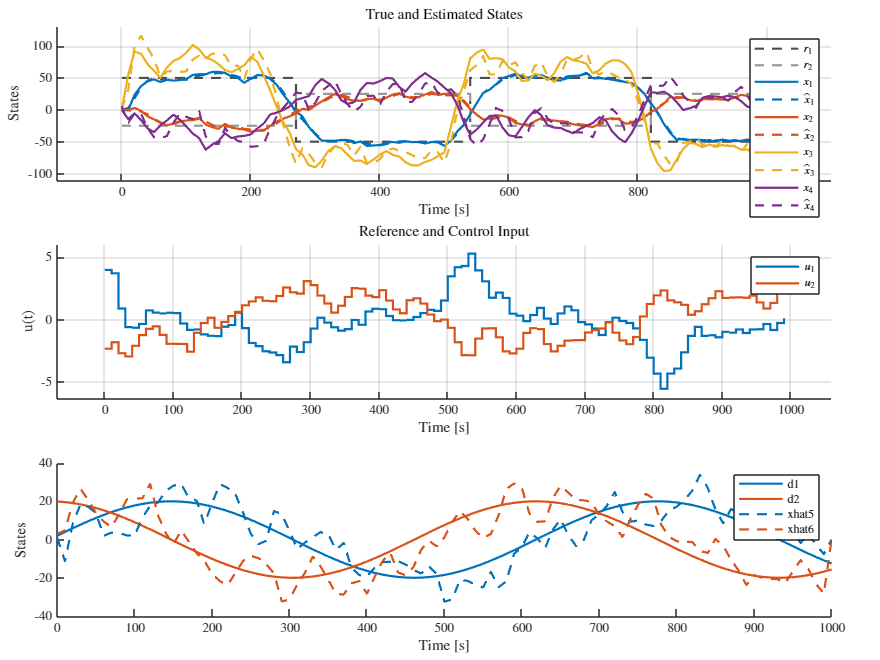



[nx, nu] = size(B_aug);
ny        = size(C_aug,1);


[ Kf, ~, ~ ] = dlqe(A_aug, eye(nx), C_aug, R1_aug, R2);  
[Pp,~,~] = idare(A_aug', C_aug', R1_aug, R2);

Po = inv(inv(Pp) + C_aug'*inv(R2)*C_aug);

% Compute stationary Kalman gain
% Kf = P * C' / (C * P * C' + R2);
Kf = Po * C_aug' / (C_aug * Po * C_aug' + R2);


%% 3) GPC tuning parameters
Np  = 10;                                      % prediction horizon
Qy  = kron(eye(Np), eye(ny));                  % output‐tracking weight
Ru  = 100 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Phi     = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);

for i = 1:Np
    Phi((i-1)*ny+1:i*ny, :) = C_aug * A_aug^(i-1);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;

        if i == j
            Gamma_y(idx_row, idx_col) = D_aug;  % Diagonal: D
        else
            Gamma_y(idx_row, idx_col) = C_aug * A_aug^(i-j) * B_aug;  % Lower-triangular: CA^(i-j)B
        end
    end
end

% Precompute Hessian for QP
H = Gamma_y' * Qy * Gamma_y + Ru;
opts = optimoptions('quadprog','Display','off');

%% 5) Reference signal (±10 square wave on output 1)
ref1 = 50 * square(2*pi*(2/(Nsim+ Np))*(1:Nsim + Np), 50);
ref2 = -0.5*ref1; %zeros(1, Nsim + Np);
ref  = [ref1; ref2];    


%% 6) Preallocate
x     = zeros(nx-2,   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
d1  = [12* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    -6* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    ];   % estimated state

d2 =[12* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    -6* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    -4* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50);
    8* square(2*pi*(2/(2*Nsim+ 1))*(1:Nsim + 1), 50)]; 
% d = 100*[ones(1,Nsim+1);
%     -ones(1,Nsim+1)];
d3 = 20*[sin(1/10*(1:Nsim+1));cos(1/10*(1:Nsim+1))];
u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
xhat_pred = xhat(:,1);
Xpred   = zeros(nx, Np+1, Nsim);  % store Np‐step predictions
rng(0);  % for reproducibility

%% 7) Main simulation loop
for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), R2)';
    
    %--- Kalman correct
    innov      = y(:,k) - C_aug*xhat_pred;
    xhat(:,k)  = xhat_pred + Kf * innov;

    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference
    f = Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);

    %--- apply control law
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;
    % u(:, k) =  [0;0];

    
    % Compute Np‐step ahead state predictions
    Xpred(:,1,k) = xhat(:,k);
    for j = 1:Np
    Uj = U_N((j-1)*nu+1:j*nu);
    Xpred(:,j+1,k) = A_aug*Xpred(:,j,k) + B_aug*Uj;
    end
    
    
    %--- simulate true system with process noise
    % x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx-2, 1), R1)' + [zeros(2,2);eye(2,2)] *d1(:,k);
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx-2, 1), R1)' + [zeros(2,2);eye(2,2)]*d3(:,k);
        
    %--- Kalman predict
    xhat_pred = A_aug*xhat(:,k) + B_aug*u(:, k);
end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

fig = figure();
fig.Position = plotPos2;
tiledlayout(3,1, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
hold on
stairs(time(1:end-1), ref(1,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
stairs(time(1:end-1), ref(2,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.6 0.6 0.6]);
names = {'$r_1$', '$r_2$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'};


for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend(names, ...
       'Location','northeast');
title('True and Estimated States');
ylim padded;
xlim padded;
grid on;
hold off

% Plot control input
nexttile;
hold on
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');
ylim padded;
xlim padded;
grid on;
hold off
% filePath = fullfile("output", 'question_1_4.png');
% exportgraphics(fig, filePath, 'Resolution', 300);
% fig = figure();
% fig.Position = plotPos;
% tiledlayout(1,1, 'Padding', 'compact', 'TileSpacing', 'compact');
nexttile;
hold on
for i = 1:2
    plot(time,  d3(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
end
for i = 5:6
    plot(time, xhat(i,:), '--', 'Color', colors(i-4,:), 'LineWidth', 1.5);
end
hold off
xlabel('Time [s]');
ylabel('States');
legend([strcat("d",string(1:2)),strcat("xhat",string(5:6))], ...
       'Interpreter','latex','Location','northeast');
filePath = fullfile("output", 'question_1_4_2.png');
exportgraphics(fig, filePath, 'Resolution', 300);

## Bonus 1.4.3

%% ------------------------------------------------------------------------
%  GPC with Stationary Kalman State Estimation for Discrete‐Time LTI System
%% ------------------------------------------------------------------------


%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0;];



[nx, nu] = size(B);
ny        = size(C,1);

%% 2) Kalman filter design (steady‐state gain)
R1 = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
R2 = eye(ny);                           % meas‐noise cov

kappa = [0.999,0.999,0.999,0.999];
% kappa = [0.99999,0.99999,0.99999,0.99999];
sigma_d = 50*[1,1,1,1];
d_in = eye(4);

A_aug = [A,d_in;zeros(4,4),diag(kappa)];

B_aug = [B;zeros(4,2)];
C_aug =  [C, zeros(2,4)];
D_aug  = D;
R1_aug = [R1,zeros(4,4);zeros(4,4),diag(sigma_d.^2)];
rank(obsv(A_aug,C_aug))

ans = 6

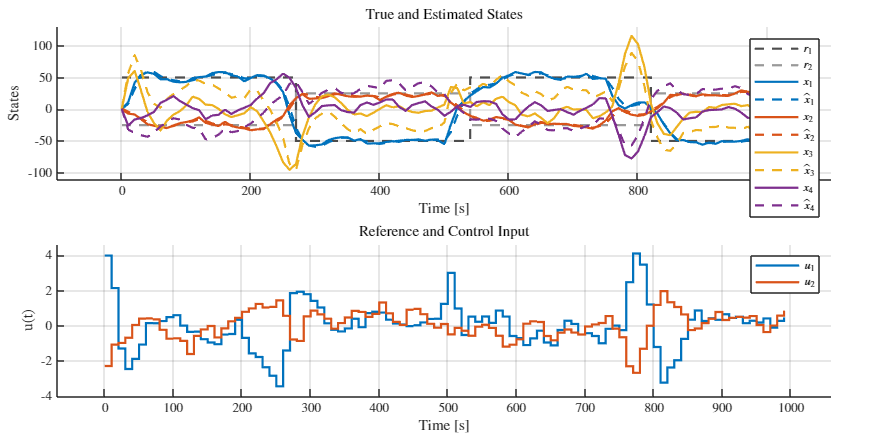


[nx, nu] = size(B_aug);
ny        = size(C_aug,1);

[ Kf, ~, ~ ] = dlqe(A_aug, eye(nx), C_aug, R1_aug, R2);  
[Pp,~,~] = idare(A_aug', C_aug', R1_aug, R2);

Po = inv(inv(Pp) + C_aug'*inv(R2)*C_aug);

% Compute stationary Kalman gain
% Kf = P * C' / (C * P * C' + R2);
Kf = Po * C_aug' / (C_aug * Po * C_aug' + R2);


%% 3) GPC tuning parameters
Np  = 10;                                      % prediction horizon
Qy  = kron(eye(Np), eye(ny));                  % output‐tracking weight
Ru  = 100 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Phi     = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);

for i = 1:Np
    Phi((i-1)*ny+1:i*ny, :) = C_aug * A_aug^(i-1);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;

        if i == j
            Gamma_y(idx_row, idx_col) = D_aug;  % Diagonal: D
        else
            Gamma_y(idx_row, idx_col) = C_aug * A_aug^(i-j) * B_aug;  % Lower-triangular: CA^(i-j)B
        end
    end
end

% Precompute Hessian for QP
H = Gamma_y' * Qy * Gamma_y + Ru;
opts = optimoptions('quadprog','Display','off');

%% 5) Reference signal (±10 square wave on output 1)
ref1 = 50 * square(2*pi*(2/(Nsim+ Np))*(1:Nsim + Np), 50);
ref2 = -0.5*ref1; %zeros(1, Nsim + Np);
ref  = [ref1; ref2];    


%% 6) Preallocate
x     = zeros(nx/2,   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
d  = [12* square(2*pi*(2/(Nsim+ 1))*(1:Nsim + 1), 50);
    -6* square(2*pi*(2/(Nsim+ 1))*(1:Nsim + 1), 50);
    -4* square(2*pi*(2/(Nsim+ 1))*(1:Nsim + 1), 50);
    8* square(2*pi*(2/(Nsim+ 1))*(1:Nsim + 1), 50)];   % estimated state

u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
xhat_pred = xhat(:,1);
Xpred   = zeros(nx, Np+1, Nsim);  % store Np‐step predictions
rng(0);  % for reproducibility

%% 7) Main simulation loop
for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), R2)';
    
    %--- Kalman correct
    innov      = y(:,k) - C_aug*xhat_pred;
    xhat(:,k)  = xhat_pred + Kf * innov;

    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference

    %--- apply control law
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;
    % u(:, k) =  [0;0];

    
    % Compute Np‐step ahead state predictions
    Xpred(:,1,k) = xhat(:,k);
    for j = 1:Np
    Uj = U_N((j-1)*nu+1:j*nu);
    Xpred(:,j+1,k) = A_aug*Xpred(:,j,k) + B_aug*Uj;
    end
    
    
    %--- simulate true system with process noise
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx/2, 1), R1)' + d(:,k);
    
        
    %--- Kalman predict
    xhat_pred = A_aug*xhat(:,k) + B_aug*u(:, k);
end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

fig = figure();
fig.Position = plotPos;
tiledlayout(2,1, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
hold on
stairs(time(1:end-1), ref(1,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
stairs(time(1:end-1), ref(2,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.6 0.6 0.6]);
names = {'$r_1$', '$r_2$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'};


for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend(names, ...
       'Location','northeast');
title('True and Estimated States');
ylim padded;
xlim padded;
grid on;
hold off

% Plot control input
nexttile;
hold on
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');
ylim padded;
xlim padded;
grid on;
hold off

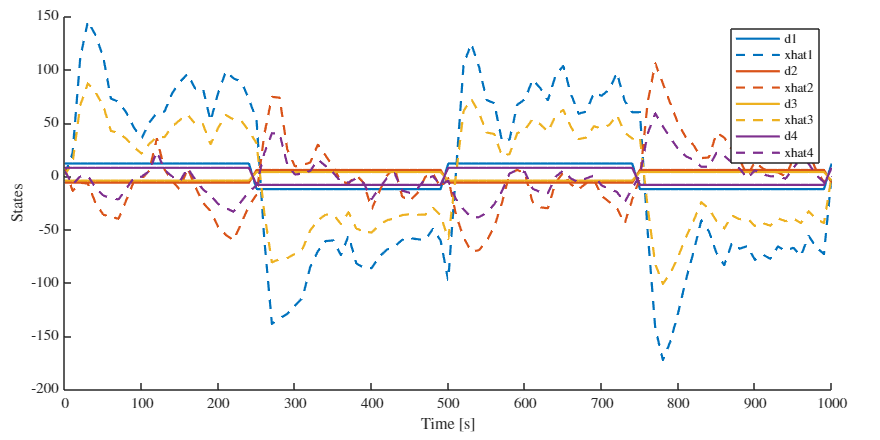

% filePath = fullfile("output", 'question_1_2_1.png');
% exportgraphics(fig, filePath, 'Resolution', 300);

fig = figure();
fig.Position = plotPos;
tiledlayout(1,1, 'Padding', 'compact', 'TileSpacing', 'compact');
nexttile;
hold on
for i = 5:8
    plot(time,  d(i-4,:),     '-',  'Color', colors(i-4,:), 'LineWidth', 1.5);
    plot(time, 10*xhat(i,:), '--', 'Color', colors(i-4,:), 'LineWidth', 1.5);
end
hold off
xlabel('Time [s]');
ylabel('States');
legend([strcat("d",string(1:nx/2));strcat("xhat",string(1:nx/2))], ...
       'Interpreter','latex','Location','northeast');


%% ------------------------------------------------------------------------
%  GPC with Stationary Kalman State Estimation for Discrete‐Time LTI System
%% ------------------------------------------------------------------------

%% 1) System definition
Ts     = 10;               % sample time [s]
Tfinal = 1000;             % total simulation time [s]
Nsim   = Tfinal / Ts;      % number of steps

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0];



[nx, nu] = size(B);
ny        = size(C,1);

%% 2) Kalman filter design (steady‐state gain)
R1 = [8.0209, 0.2260, 1.5334, 0.0812;
         0.2260, 8.0209, 0.0812, 1.5334;
         1.5334, 0.0812, 7.4082, 0.0172;
         0.0812, 1.5334, 0.0172, 7.4082];  % process‐noise cov
R2 = eye(ny);                           % meas‐noise cov


kappa = 0.9999;
sigma_d = 5;
% sigma_d = 0.1;
d_in = [1,-1,0.5,2]';

A_aug = [A,d_in;zeros(1,4),diag(kappa)]

A_aug =     0.7901    0.0238    0.1667    0.0081    1.0000
    0.0238    0.7901    0.0081    0.1667   -1.0000
    0.1667    0.0081    0.7236    0.0014    0.5000
    0.0081    0.1667    0.0014    0.7236    2.0000
         0         0         0         0    0.9999


B_aug = [B;zeros(1,2)]

B_aug =     1.4459    0.0622
    0.0622    1.4459
   13.3615    0.0077
    0.0077   13.3615
         0         0


C_aug =  [C, zeros(2,1)]

C_aug =      1     0     0     0     0
     0     1     0     0     0


R1_aug = [R1,zeros(4,1);zeros(1,4),diag(sigma_d.^2)]

R1_aug =     8.0209    0.2260    1.5334    0.0812         0
    0.2260    8.0209    0.0812    1.5334         0
    1.5334    0.0812    7.4082    0.0172         0
    0.0812    1.5334    0.0172    7.4082         0
         0         0         0         0   25.0000


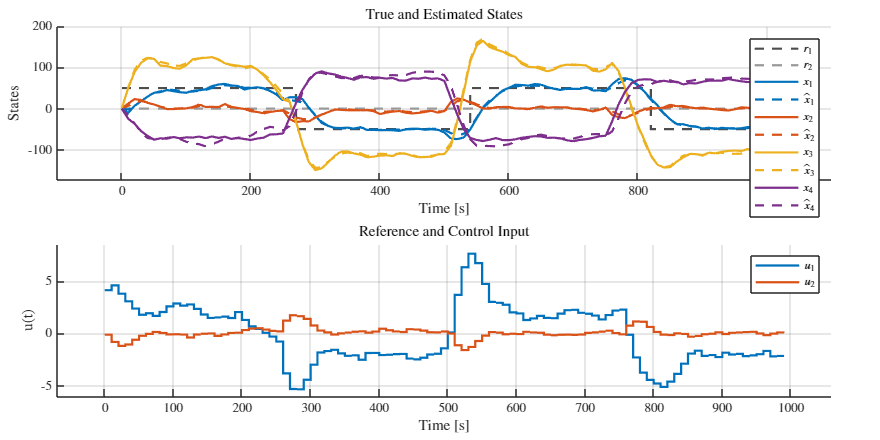



[nx, nu] = size(B_aug);
ny        = size(C_aug,1);





[ Kf, ~, ~ ] = dlqe(A_aug, eye(nx), C_aug, R1_aug, R2);  
[Pp,~,~] = idare(A_aug', C_aug', R1_aug, R2);

Po = inv(inv(Pp) + C_aug'*inv(R2)*C_aug);

% Compute stationary Kalman gain
% Kf = P * C' / (C * P * C' + R2);
Kf = Po * C_aug' / (C_aug * Po * C_aug' + R2);


%% 3) GPC tuning parameters
Np  = 10;                                      % prediction horizon
Qy  = kron(eye(Np), eye(ny));                  % output‐tracking weight
Ru  = 100 * eye(nu*Np);                       % input move weight

%% 4) Build prediction matrices
Phi   = zeros(ny*Np, nx);
Gamma_y = zeros(ny*Np, nu*Np);
for i = 1:Np
    Phi((i-1)*ny+1:i*ny, :) = C_aug * (A_aug^i);
    for j = 1:i
        idx_row = (i-1)*ny+1 : i*ny;
        idx_col = (j-1)*nu+1 : j*nu;
        Gamma_y(idx_row, idx_col) = C_aug * (A_aug^(i-j)) * B_aug;
    end
end

% Precompute Hessian for QP
H = Gamma_y' * Qy * Gamma_y + Ru;
opts = optimoptions('quadprog','Display','off');

%% 5) Reference signal (±10 square wave on output 1)
ref1 = 50 * square(2*pi*(2/(Nsim+ Np))*(1:Nsim + Np), 50);
ref2 = zeros(1, Nsim + Np);
ref  = [ref1; ref2];       % size 2×Nsim

%% 6) Preallocate
x     = zeros(nx-length(sigma_d),   Nsim+1);   % true state
xhat  = zeros(nx,   Nsim+1);   % estimated state
% d  = 5*ones(1,   Nsim+1);
d = -10*square(2*pi*(2/(Nsim+ 1))*(1:Nsim + 1), 50) ; %+ mvnrnd(0,1,Nsim + 1)';

u     = zeros(nu,   Nsim);
y     = zeros(ny,   Nsim);
P    = 5*eye(nx);        % init error‐covariance
P_pred    = P;
xhat_pred = xhat(:,1);
Xpred   = zeros(nx, Np+1, Nsim);  % store Np‐step predictions
rng(0);  % for reproducibility

%% 7) Main simulation loop
u_prev = zeros(nu,1);
for k = 1:Nsim
    %--- simulate measurement y(k) with noise
    y(:,k) = C*x(:,k) + mvnrnd(zeros(ny,1), R2)';

    %--- Kalman correct
    innov      = y(:,k) - C_aug*xhat_pred;
    xhat(:,k)  = xhat_pred + Kf * innov;
    
    
    %--- GPC: form QP linear term
    r_win = reshape(ref(:, k:k+Np-1), [], 1);% stacked reference

    %--- apply control law
    U_N = -inv(Gamma_y' * Qy * Gamma_y + Ru) * Gamma_y' * Qy * (Phi * xhat(:, k) - r_win);
    
    %--- apply only first move
    % u(:, k) = U_N(1:nu);
    u(:, k) = [eye(nu), zeros(nu,nu*Np - nu)] * U_N;

    
    % Compute Np‐step ahead state predictions
    Xpred(:,1,k) = xhat(:,k);
    for j = 1:Np
    Uj = U_N((j-1)*nu+1:j*nu);
    Xpred(:,j+1,k) = A_aug*Xpred(:,j,k) + B_aug*Uj;
    end
    
    
    %--- simulate true system with process noise
    x(:, k+1) = A * x(:, k) + B * u(:, k) + mvnrnd(zeros(nx - length(sigma_d), 1), R1)' + d_in*d(:,k);
        
    %--- Kalman predict
    xhat_pred = A_aug*xhat(:,k) + B_aug*u(:, k);
end

%% 8) Plotting
time   = 0:Ts:Tfinal;
colors = lines(4);

fig = figure();
fig.Position = plotPos;
tiledlayout(2,1, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
hold on
stairs(time(1:end-1), ref(1,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.3 0.3 0.3]);
stairs(time(1:end-1), ref(2,1:end-Np), '--', 'LineWidth', 1.5, 'Color', [0.6 0.6 0.6]);
names = {'$r_1$', '$r_2$', '$x_1$','$\hat{x}_1$','$x_2$','$\hat{x}_2$','$x_3$','$\hat{x}_3$','$x_4$','$\hat{x}_4$'};


for i = 1:4
    plot(time,     x(i,:),     '-',  'Color', colors(i,:), 'LineWidth', 1.5);
    plot(time, xhat(i,:), '--', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('Time [s]');
ylabel('States');
legend(names, ...
       'Location','northeast');
title('True and Estimated States');
ylim padded;
xlim padded;
grid on;
hold off

% Plot control input
nexttile;
hold on
stairs(time(1:end-1), u(:,:)', '-',  'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('u(t)');
legend('$u_1$','$u_2$');
title('Reference and Control Input');
ylim padded;
xlim padded;
grid on;
hold off

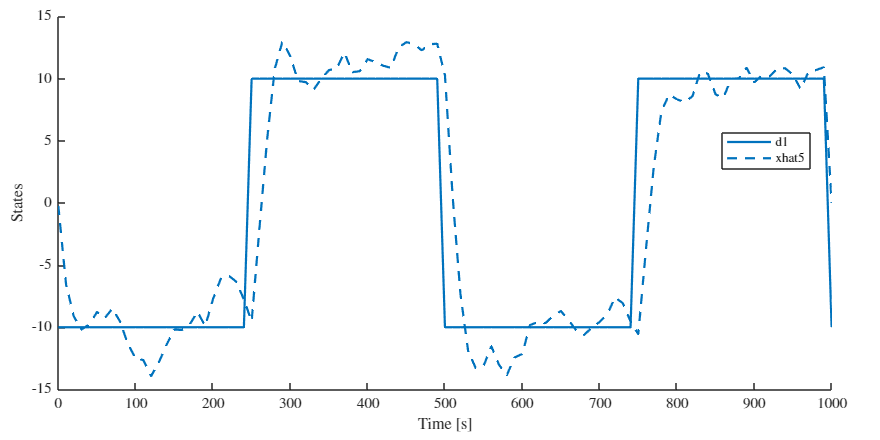

% filePath = fullfile("output", 'question_1_2_1.png');
% exportgraphics(fig, filePath, 'Resolution', 300);
fig = figure();
fig.Position = plotPos;
tiledlayout(1,1, 'Padding', 'compact', 'TileSpacing', 'compact');
nexttile;
hold on
plot(time,  d(1,:),     '-',  'Color', colors(1,:), 'LineWidth', 1.5);
plot(time, xhat(5,:), '--', 'Color', colors(1,:), 'LineWidth', 1.5);

hold off
xlabel('Time [s]');
ylabel('States');
legend([strcat("d",string(1:1));strcat("xhat",string(5:5))], ...
       'Interpreter','latex','Location','best');